# Network Milestone - Alexander Wang (aw3494), Nick Fiorovanti (nef46)

## Step 1. Set up Network Representation

% Number of individuals
N = 100;

% Random symmetric matrix
network = randi([0, 1], N);
network = triu(network, 1);
network = network + network';

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Create random ages for individuals in contact network
age = ones(N,1); 
for p = 1:size(age,1)
    age(p) = randi(80);
end

% Randomly assign a few individuals as Infected
num_initially_infected = 0.05*N;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;

% Initial stats:
initial_infected_proportion = sum(state)/N; 
initial_susceptible_proportion = sum(state==0)/N;

## Step 2. Simulate

% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 365;                                 % days
expose_prob = 0.05;                             % exposure prob
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_exposed = zeros(num_days, 1);               % Vector of exposed individuals each day
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
hospitalization_rate = 0.15;                    %https://gis.cdc.gov/grasp/COVIDNet/COVID19_3.html 
% positive_rate = 0.12875/7;  % by week           % Percent Positive Testing: averaged peaks of % positive weekly https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00
% MAKE ASSUMPTION - IF EACH EXPOSED INDIVIDUAL AT-HOME TESTS, AND THEN TESTS POSITIVE, THEY
% SOCIAL DISTANCE AND CANNOT INFECT OTHERS
% ORRRRRR
socialdist_prob = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];  % no statistic for social distancing probability when healthy, so we made it 50/50 chance
% 0.75 - quarantining rate  - https://thehill.com/changing-america/well-being/medical-advances/491760-3-in-4-americans-say-they-are-self-isolating-in/#:~:text=Approximately%2075%20percent%20of%20U.S.%20residents%20are%20self-isolating,coronavirus%20and%20is%20being%20enforced%20across%20the%20country.
% find quarantining rate to find acceptable loss of individuals

% Hosp death rate approximated from: 
% https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm
hosp_death_rate_29 = 0.03/7;
hosp_death_rate_59 = 0.07/7;
hosp_death_rate_plus = 0.18/7;

Other rates

% hospitalization_rate = 0.0015;                  % hospitalization rate https://www.nytimes.com/interactive/2023/us/covid-cases.html

%hospitalization_rate = 1.2/100000; % https://www.nytimes.com/interactive/2023/us/covid-cases.html

% hospitalization_rate = 0.3; % [https://www.economist.com/graphic-detail/2021/03/13/our-covid-19-model-estimates-odds-of-hospitalisation-and-death](https://www.economist.com/graphic-detail/2021/03/13/our-covid-19-model-estimates-odds-of-hospitalisation-and-death)

% death_rate = 0.1625;                % percent deaths: averaged peaks of % death attributed to covid https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00

% death_rate = 0.3/100000 % https://www.nytimes.com/interactive/2023/us/covid-cases.html

% death_rate = 1.1/100 % https://coronavirus.jhu.edu/data/mortality

% death_rate = 0.06; % https://ourworldindata.org/mortality-risk-covid

% hosp_death_rate = 0.10/7; % by week, % [https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm](https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm)

% death_rate = 0.0028;                          % OLD DEATH RATE: gross mortality rate https://www.worldometers.info/coronavirus/coronavirus-death-rate/

% quarantining_rate = 0.75;                       % quarantining rate  - https://thehill.com/changing-america/well-being/medical-advances/491760-3-in-4-americans-say-they-are-self-isolating-in/#:~:text=Approximately%2075%20percent%20of%20U.S.%20residents%20are%20self-isolating,coronavirus%20and%20is%20being%20enforced%20across%20the%20country.

This figure displays the maxima along the 
mean of 10 simulation iterations for each group 
and the times in which they occur 
for quarantining rate of 0.5.

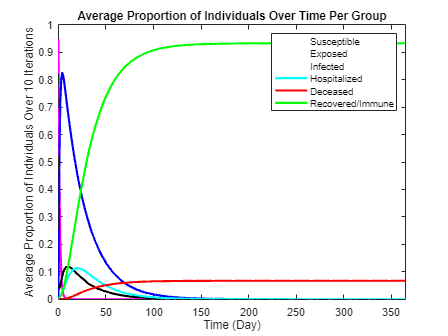

This table displays the maxima along the 
mean of 10 simulation iterations for each group 
and the times in which they occur 
for quarantining rate of 0.5.

                                         Max Susceptible    Max Exposed    Max Infected    Max Deceased    Max Hospitalized    Max Immune
                                         _______________    ___________    ____________    ____________    ________________    __________

    Proportions Across Simulation            0.44204          0.82488        0.11875         0.06729           0.11357          0.93271  
    Times for Max Average Proportions              1                4              9             268                19              257  



% Store infected/susceptible state to recall for all iterations
state_orig = state;

% RECAP: SUSCEPTIBLE = 0, INFECTED = 1, EXPOSED = 2, HOSPITALIZED = 3,
% RECOVERED/IMMUNE = 4, DEAD = NaN
for c = 1:11
        % Repeat model for 10 iterations to average findings
        for l = 1:1000
        
            % initialize the iteration state of susceptible and infected to original state of infection
            state = state_orig; 
            
            % For each day in the year
            for day = 1:num_days      
                
                % For each individual in the contact network
                for i = 1:N                                 
                    
                    % If the individual is infected
                    if state(i) == 1
                        
                        % Find the other individuals in the network they are in
                        % contact with 
                        contacts = find(network(i, :));     
                        
                        % For all contacts in network 
                        for j = contacts               
                            
                            % Randomly generate a number to decide chance of
                            % contact becoming exposed if susceptible
                            exposed_diceroll = rand;
        
                            % If contact is susceptible
                            if state(j) == 0
        
                               % generate random chance for not social distancing
                               social_dist_diceroll = rand; 
                               
                               % If individual didn't social distance
                               if social_dist_diceroll > socialdist_prob(c)
        
                                    % See if the probability is within the expected for
                                    % exposure
                                    if exposed_diceroll < expose_prob 
            
                                        % If so, susceptible individual becomes exposed
                                        % to COVID
                                        state(j) = 2; 
                                    end
                               end
                            end
                        end
        
                        % now move onto the current infected patient 
        
                        % Since the patient is infected, there is a chance they
                        % will recover 
                        
                        % Randomly generate this chance
                        recovery_diceroll = rand;
        
                        % Randomly generate a chance for hospitalization as well 
                        hospitalized_diceroll = rand;
                        % IMMUNITY LASTS ABOUT 500 DAYS (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                        % If recovery chance is within expected probability
                        if recovery_diceroll < recover_prob
        
                            % Infected individual becomes susceptible again
                            % (disregard short-term immunity as individuals have
                            % been found to get covid multiple times) 
                            state(i) = 4; 
                        
                            % MAKE ASSUMPTION THAT IF PEOPLE ARE SICK, THEY'LL GO
                            % TO HOSPITAL - ONLY PLACE THEY WOULD DIE
        %                 % If chance is not within recovery and expectation for death
        %                 elseif recovery_diceroll > (1-death_rate) && hospitalized_diceroll > hospitalization_rate
        %                    
        %                     % individual gets removed from the network
        %                     state(i) = NaN;                           
        %                 
                        % if chance not within recovery and hospitalization is
                        % probable
                        elseif recovery_diceroll > recover_prob && hospitalized_diceroll < hospitalization_rate
        
                            % infected individual instead becomes hospitalized
                            state(i) = 3;
                        end
                        
                    % If the individual is not infected, but is exposed, 
                    elseif state(i) == 2 
                        
                        % Generate random chance for individual to become infected
                        infected_diceroll = rand; 
        
                        % If chance is within expected
                        if infected_diceroll <  infect_prob
        
                            % Convert exposed individual to infected
                            state(i) = 1;
                        end
        
                    % If individual is hospitalized
                    elseif state(i) == 3   
                        
                        % Generate random recovery chance
                        recovery_diceroll = rand; 
        
                        % Generate random hospitalization chance
                        hospitalized_diceroll = rand;
        
                        % Generate random death chance
                        reaper_diceroll = rand;
                        
                        % IMMUNITY FOR 500 days (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                        % If recovery is expected
                        if recovery_diceroll < recover_prob 
                            
                            % Hospitalized individual becomes susceptible and can
                            % go home
                            state(i) = 4;
                        
                        % If individual is still symptomatic and expected by chance
                        elseif hospitalized_diceroll < hospitalization_rate
        
                            % Remain in hospital
                            state(i) = 3; 
                        end
        
                        if age(i) <= 29
                            if reaper_diceroll < hosp_death_rate_29
                                state(i) = NaN;
                            end
                        elseif age(i) <= 59
                            if reaper_diceroll < hosp_death_rate_59
                                state(i) = NaN;
                            end
                        else 
                            if reaper_diceroll < hosp_death_rate_plus
                                state(i) = NaN;
                            end
                        end
        %                 % If individual is hospitalized, and expected for death
        %                 elseif reaper_diceroll < hosp_death_rate 
        %                     state(i) = NaN;
        %                 end 
        
                    % If susceptible, 
                    elseif state(i) == 0 
                        social_dist_diceroll = rand; 
                        if social_dist_diceroll > socialdist_prob(c) % then did not social distance and gets exposed to covid-19
                            state(i) = 2;
                        end
                    end
                end  
                % Record the number of exposed and infected individuals
                num_susceptible(day) = sum(state == 0);
                num_infected(day) = sum(state == 1);
                num_exposed(day) = sum(state == 2);
                num_hospitalized(day) = sum(state == 3);
                num_immune(day) = sum(state == 4); 
                num_deceased(day) = sum(isnan(state));
            end
        
        % Store all of the simulated data for this iteration in the accumulation
        % variables
        num_exposed_accumulated(l,:) = num_exposed';
        num_infected_accumulated(l,:) = num_infected';
        num_susceptible_accumulated(l,:) = num_susceptible';
        num_deceased_accumulated(l,:) = num_deceased'; 
        num_hospitalized_accumulated(l,:) = num_hospitalized';
        num_immune_accumulated(l, :) = num_immune';
        end

    if c == 6
    fprintf('This figure displays the maxima along the \nmean of 10 simulation iterations for each group \nand the times in which they occur \nfor quarantining rate of 0.5.')   
    % Plot the number of exposed and infected individuals over time
    figure;
    
    % Plot susceptible
    plot(0:num_days, [initial_susceptible_proportion mean(num_susceptible_accumulated)/N], 'Color', 'Magenta', 'DisplayName', 'Susceptible', 'LineWidth', 2);
    hold on 
    % Plot exposed proportion 
    plot(0:num_days, [0 mean(num_exposed_accumulated)/N], 'Color', 'Blue', 'DisplayName', 'Exposed', 'LineWidth', 2);
    
    % Plot infectious proportion
    plot(0:num_days, [initial_infected_proportion mean(num_infected_accumulated)/N], 'Color', 'Black', 'DisplayName', 'Infected', 'LineWidth', 2);
    
    % Plot hospitalized proportion
    plot(0:num_days, [0 mean(num_hospitalized_accumulated)/N], 'Color', 'Cyan', 'DisplayName', 'Hospitalized', 'LineWidth', 2)
    
    % Plot deceased proportion
    plot(0:num_days, [0 mean(num_deceased_accumulated)/N], 'Color', 'Red', 'DisplayName', 'Deceased', 'LineWidth', 2)
    
    % Plot immune proportion
    plot(1:num_days, mean(num_immune_accumulated)/N, 'Color', 'Green', 'DisplayName', 'Recovered/Immune', 'LineWidth', 2)
    % Label figure
    xlabel('Time (Day)');
    ylabel('Average Proportion of Individuals Over 10 Iterations');
    xlim([0 num_days])
    title('Average Proportion of Individuals Over Time Per Group')
    legend()
    end

% Mean Peak Susceptible
avg_susceptible = mean(num_susceptible_accumulated); 
% Mean Peak Exposed
avg_exposed = mean(num_exposed_accumulated);
% Mean Peak Infected 
avg_infected = mean(num_infected_accumulated);
% Mean Peak Deceased
avg_deceased = mean(num_deceased_accumulated);
% Mean Peak Hospitalized
avg_hospitalized = mean(num_hospitalized_accumulated);
% Mean Peak Immune
avg_immune = mean(num_immune_accumulated);

% % Mean Peak Susceptible
% peak_susceptible = mean(max(num_susceptible_accumulated)); 
% % Mean Peak Exposed
% peak_exposed = mean(max(num_exposed_accumulated));
% % Mean Peak Infected 
% peak_infected = mean(max(num_infected_accumulated));
% % Mean Peak Deceased
% peak_deceased = mean(max(num_deceased_accumulated));
% % Mean Peak Hospitalized
% peak_hospitalized = mean(max(num_hospitalized_accumulated));
% % Mean Peak Immune
% peak_immune = mean(max(num_immune_accumulated));
 

max_susceptible = max(avg_susceptible);
max_exposed = max(avg_exposed);
max_infected = max(avg_infected);
max_deceased = max(avg_deceased);
max_hospitalized = max(avg_hospitalized);
max_immune = max(avg_immune);
time_susceptible = find(avg_susceptible == max_susceptible);
time_exposed = find(avg_exposed == max_exposed);
time_infected = find(avg_infected == max_infected);
time_deceased = find(avg_deceased == max_deceased);
time_hospitalized = find(avg_hospitalized == max_hospitalized);
time_immune = find(avg_immune == max_immune);

max_c(:,c) =[max_susceptible/N;max_exposed/N; max_infected/N; max_deceased/N; max_hospitalized/N; max_immune/N];
time_c(:,c) = [time_susceptible(1); time_exposed(1);time_infected(1); time_deceased(1); time_hospitalized(1); time_immune(1)];
    if c == 6
        fprintf('This table displays the maxima along the \nmean of 10 simulation iterations for each group \nand the times in which they occur \nfor quarantining rate of 0.5.') 
        t1 = table([max_susceptible/N; time_susceptible(1)], [max_exposed/N; time_exposed(1)], [max_infected/N; time_infected(1)], [max_deceased/N; time_deceased(1)], [max_hospitalized/N; time_hospitalized(1)], [max_immune/N; time_immune(1)]);
        t1.Properties.VariableNames = {'Max Susceptible', 'Max Exposed', 'Max Infected', 'Max Deceased', 'Max Hospitalized', 'Max Immune'};
        t1.Properties.RowNames = {'Proportions Across Simulation', 'Times for Max Average Proportions'};
        disp(t1)    
    end
end

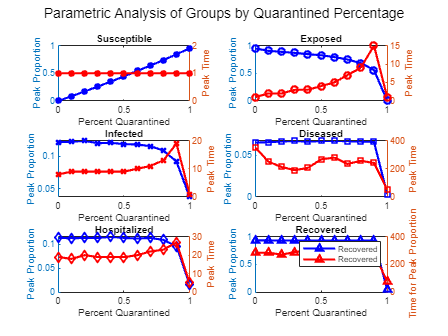


figure
sgtitle('Parametric Analysis of Groups by Quarantined Percentage')
hold on 
for k = 1:6 
    if k == 1
        subplot(3,2,1)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-b*', 'LineWidth', 2,'DisplayName', 'Susceptible')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:),'-r*','LineWidth', 2, 'DisplayName', 'Susceptible')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Susceptible')
    elseif k == 2
        subplot(3,2,2)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bo','LineWidth', 2,'DisplayName', 'Exposed')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:),'-ro', 'LineWidth', 2, 'DisplayName', 'Exposed')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Exposed')
    elseif k == 3
        subplot(3,2,3)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bx','LineWidth', 2,'DisplayName', 'Infected')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rx','LineWidth', 2, 'DisplayName', 'Infected')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Infected')
    elseif k == 4
        subplot(3,2,4)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bs','LineWidth', 2,'DisplayName', 'Diseased')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rs','LineWidth', 2, 'DisplayName', 'Diseased')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Diseased')
    elseif k == 5
        subplot(3,2,5)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bd','LineWidth', 2,'DisplayName', 'Hospitalized')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rd','LineWidth', 2, 'DisplayName', 'Hospitalized')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Hospitalized')
    elseif k == 6
        subplot(3,2,6)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-b^','LineWidth', 2,'DisplayName', 'Recovered')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-r^','LineWidth', 2, 'DisplayName', 'Recovered')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Recovered')
    end
end
xlabel('Percent Quarantined')
legend
yyaxis left 
ylabel('Peak Proportion')
yyaxis right
ylabel('Time for Peak Proportion')
hold off

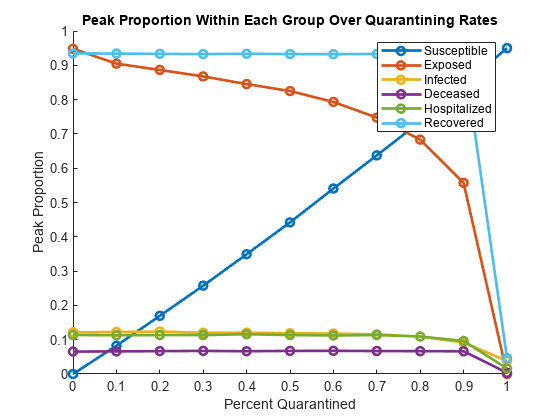



figure
hold on 
for k = 1:6 
    if k == 1
        plot(socialdist_prob, max_c(k,:), '-o','LineWidth', 2,'DisplayName', 'Susceptible')
    elseif k == 2
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Exposed')
    elseif k == 3
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Infected')
    elseif k == 4
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Deceased')
    elseif k == 5
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Hospitalized')
    elseif k == 6
        plot(socialdist_prob, max_c(k,:), '-o', 'LineWidth', 2,'DisplayName', 'Recovered')
    end
end
xlabel('Percent Quarantined')
legend
ylabel('Peak Proportion')
title('Peak Proportion Within Each Group Over Quarantining Rates')
hold off

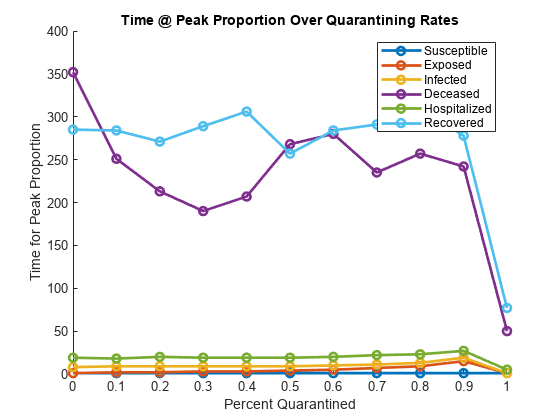


figure
hold on 
for k = 1:6 
    if k == 1
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Susceptible')
    elseif k == 2
        plot(socialdist_prob, time_c(k,:),'-o', 'LineWidth', 2, 'DisplayName', 'Exposed')
    elseif k == 3
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Infected')
    elseif k == 4
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Deceased')
    elseif k == 5
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Hospitalized')
    elseif k == 6
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Recovered')
    end
end
xlabel('Percent Quarantined')
legend
ylabel('Time for Peak Proportion')
title('Time @ Peak Proportion Over Quarantining Rates')